# Import Data

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Seconds", "Volts"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
Wave000 = readtable("/home/locadmin/Repositories/Fast Fourier Transfor/WaveFiles/Wave000.csv", opts);

% Convert to output type
Wave000 = table2array(Wave000);

% Clear temporary variables
clear opts

% Display results
Wave000

Wave000 =          0         0
    0.0000    0.0265
    0.0000    0.0529
    0.0000    0.0788
    0.0000    0.1042
    0.0000    0.1287
    0.0000    0.1523
    0.0000    0.1747
    0.0000    0.1958
    0.0000    0.2154


## Plot the Data

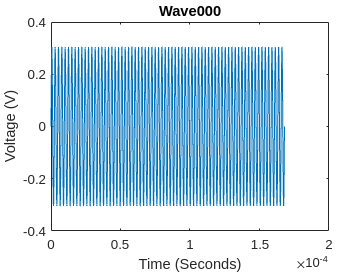

% Create plot of Wave000 and Wave000
h = plot(Wave000(:,1),Wave000(:,2),"DisplayName","Wave000");

% Add xlabel, ylabel, title, and legend
xlabel("Time (Seconds)")
ylabel("Voltage (V)")
title("Wave000")

## Extract Signal Information

Fs = 1 / (Wave000(2,1) - Wave000(1,1));
L = length(Wave000);

## FFT

% Compute the Fourier transform of the signal.

Y = fft(Wave000(:,2));

% Compute the two-sided spectrum P2. Then compute the single-sided spectrum P1 based on P2 and the even-valued signal length L.
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

P1(2:end-1) = 2*P1(2:end-1);

% Define the frequency domain f and plot the single-sided amplitude spectrum P1. The amplitudes are not exactly at 0.7 and 1, as expected, because of the added noise. On average, longer signals produce better frequency approximations.
f = Fs*(0:(L/2))/L;
[M, I] = max(P1);

M = 0.3044

I = 71

f1 = f(I);

f1 = 4.1667e+05

## Plot the Spectrum

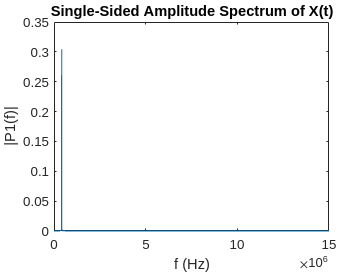

plot(f,P1) 
title("Single-Sided Amplitude Spectrum of X(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")